clear; clc
close all

c_rate = ["0_5C", "1C", "1_5C", "2C"];
plot_legend = ["0.5C", "1C", "1.5C", "2C"];
pybammDataPrefix = "Discharge_";
simDataPrefix = "result_";

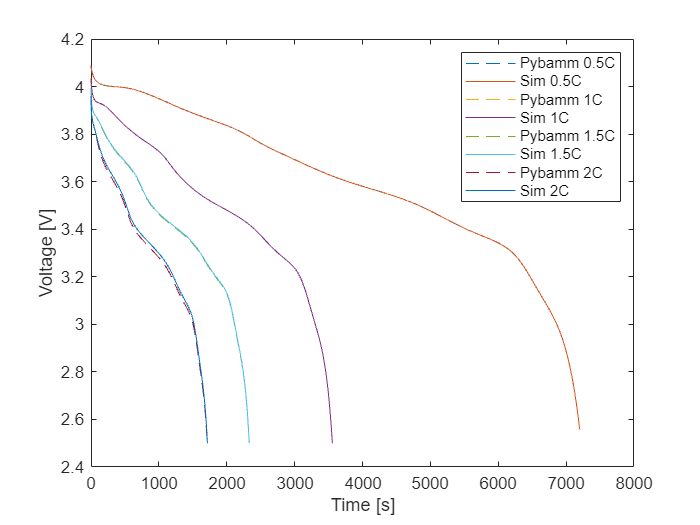

for i=1:numel(c_rate)
    pybammData = evalin("caller",sprintf('load(''%s'')',strcat(pybammDataPrefix,c_rate(i),'.mat')));
    simData = evalin("caller",sprintf('load(''%s'')',strcat(simDataPrefix,c_rate(i),'.mat')));
    
    idx = find(mod(pybammData.time,1)==0);   
    pybammData.voltage = pybammData.voltage(idx);
    pybammData.time = pybammData.time(idx);
    
    lastidx = find(simData.result.time == pybammData.time(end));

    error = pybammData.voltage - simData.sim_voltage(1:lastidx)';

    plot(pybammData.time, pybammData.voltage, '--', 'DisplayName', sprintf('Pybamm %s',plot_legend(i)))
    hold on
    plot(simData.result.time, simData.sim_voltage, 'DisplayName', sprintf('Sim %s',plot_legend(i)))    
    
    clear pybammData simData error
end
hold off
xlabel('Time [s]'); ylabel('Voltage [V]');
legend show

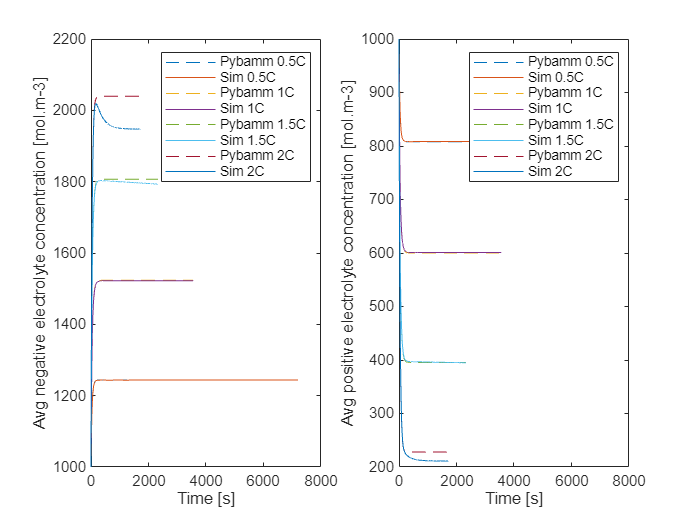

for i=1:numel(c_rate)
    pybammData = evalin("caller",sprintf('load(''%s'')',strcat(pybammDataPrefix,c_rate(i),'.mat')));
    simData = evalin("caller",sprintf('load(''%s'')',strcat(simDataPrefix,c_rate(i),'.mat')));
    
    idx = find(mod(pybammData.time,1)==0); 
    pybammData.time = pybammData.time(idx);
    pybammData.ce1 = pybammData.ce1(:,idx);
    pybammData.ce3 = pybammData.ce3(:,idx);

    subplot(1,2,1)
    plot(pybammData.time, pybammData.ce1(1,:), '--', 'DisplayName', sprintf('Pybamm %s',plot_legend(i)))
    hold on
    plot(simData.result.time, simData.ce1avg, 'DisplayName', sprintf('Sim %s',plot_legend(i)))    
    
    subplot(1,2,2)
    plot(pybammData.time, pybammData.ce3(end,:), '--', 'DisplayName', sprintf('Pybamm %s',plot_legend(i)))
    hold on
    plot(simData.result.time, simData.ce3avg, 'DisplayName', sprintf('Sim %s',plot_legend(i)))    

    clear pybammData simData error
end
subplot(1,2,1)
hold off
xlabel('Time [s]'); ylabel('Avg negative electrolyte concentration [mol.m-3]');
legend show
subplot(1,2,2)
hold off
xlabel('Time [s]'); ylabel('Avg positive electrolyte concentration [mol.m-3]');
legend show

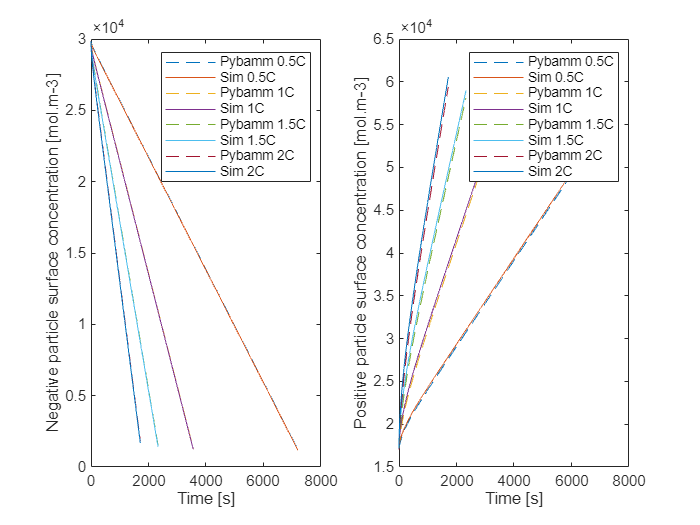

for i=1:numel(c_rate)
    pybammData = evalin("caller",sprintf('load(''%s'')',strcat(pybammDataPrefix,c_rate(i),'.mat')));
    simData = evalin("caller",sprintf('load(''%s'')',strcat(simDataPrefix,c_rate(i),'.mat')));
    
    idx = find(mod(pybammData.time,1)==0); 
    pybammData.time = pybammData.time(idx);
    pybammData.cs1 = pybammData.cs1(:,idx);
    pybammData.cs3 = pybammData.cs3(:,idx);

    subplot(1,2,1)
    plot(pybammData.time, pybammData.cs1(end,:), '--', 'DisplayName', sprintf('Pybamm %s',plot_legend(i)))
    hold on
    plot(simData.result.time, simData.cs1_sim(1,:), 'DisplayName', sprintf('Sim %s',plot_legend(i)))    
    
    subplot(1,2,2)
    plot(pybammData.time, pybammData.cs3(end,:), '--', 'DisplayName', sprintf('Pybamm %s',plot_legend(i)))
    hold on
    plot(simData.result.time, simData.cs3_sim(1,:), 'DisplayName', sprintf('Sim %s',plot_legend(i)))    

    clear pybammData simData error
end
subplot(1,2,1)
hold off
xlabel('Time [s]'); ylabel('Negative particle surface concentration [mol.m-3]');
legend show
subplot(1,2,2)
hold off
xlabel('Time [s]'); ylabel('Positive particle surface concentration [mol.m-3]');
legend show